% compressed sensing example
%
%___DESCRIPTION___
% MATLAB implementation of compressive sensing example as described in R.
% Baraniuk, Compressive Sensing, IEEE Signal Processing Magazine, [118],
% July 2007. The code acquires 250 averaged random measurements of a 2500
% pixel image. We assume that the image has a sparse representation in the
% DCT domain (not very sparse in practice). Hence the image can be
% recovered from its compressed form using basis pursuit.
%
%___DEPENDENCIES___
% Requires the MATLAB toolbox l_1-MAGIC: Recovery of Sparse Signals via Convex
% Programming v1.11 by J. Candes and J. Romberg, Caltech, 2005. 
%
%___VARIABLES___
% x = original signal (nx1) y = compressed signal (mx1) Phi = measurement
% matrix (mxn) Psi = Basis functions (nxn) Theta = Phi * Psi (mxn) s =
% sparse coefficient vector (to be determined) (nx1)
%
%___PROBLEM___
% Invert the matrix equation y = Theta * s and therefore recover hat_x as
% k-sparse linear combination of basis functions contained in Psi. Note
% also that y = Phi * x.
%
%___SOLUTION___
% Let Phi be a matrix of i.i.d. Gaussian variables. Solve matrix inversion
% problem using basis pursuit (BP).
%___CREATED___
% o By S.Gibson, School of Physical Sciences, University of Kent. 
% o 1st May, 2013.
% o version 1.0
% o NOTES: If the max number of iterations exceeds 25, error sometimes
%   occurs in l1eq_pd function call.
%
%___DISCLAIMER___
% The code below is my interpretation of Baraniuk's compressed sensing
% article. I don't claim to be an authority on the subject!
%___INPUT IMAGE___
clear, close all, clc
A = imread('cameraman.tif');
A = imresize(A,[50 50]);
%A = A([50:99],[50:99]);
x = double(A(:));
n = length(x);
%___MEASUREMENT MATRIX___
m = 2000; % NOTE: small error still present after increasing m to 1500;
Phi = randn(m,n);
    %__ALTERNATIVES TO THE ABOVE MEASUREMENT MATRIX___ 
    %Phi = (sign(randn(m,n))+ones(m,n))/2; % micro mirror array (mma) e.g. single
    %pixel camera Phi = orth(Phi')'; % NOTE: See Candes & Romberg, l1
    %magic, Caltech, 2005.
%___COMPRESSION___
y = Phi*x;
%___THETA___
% NOTE: Avoid calculating Psi (nxn) directly to avoid memory issues.
Theta = zeros(m,n);
for ii = 1:n
    ii;
    ek = zeros(1,n);
    ek(ii) = 1;
    psi = idct(ek)';
    Theta(:,ii) = Phi*psi;
end
%___l2 NORM SOLUTION___ s2 = Theta\y; %s2 = pinv(Theta)*y
s2 = pinv(Theta)*y;
%___BP SOLUTION___
s1 = l1eq_pd(s2,Theta,Theta',y,5e-3,20); % L1-magic toolbox
%x = l1eq_pd(y,A,A',b,5e-3,32);
%___DISPLAY SOLUTIONS___
plot(s2,'b'), hold

Current plot held


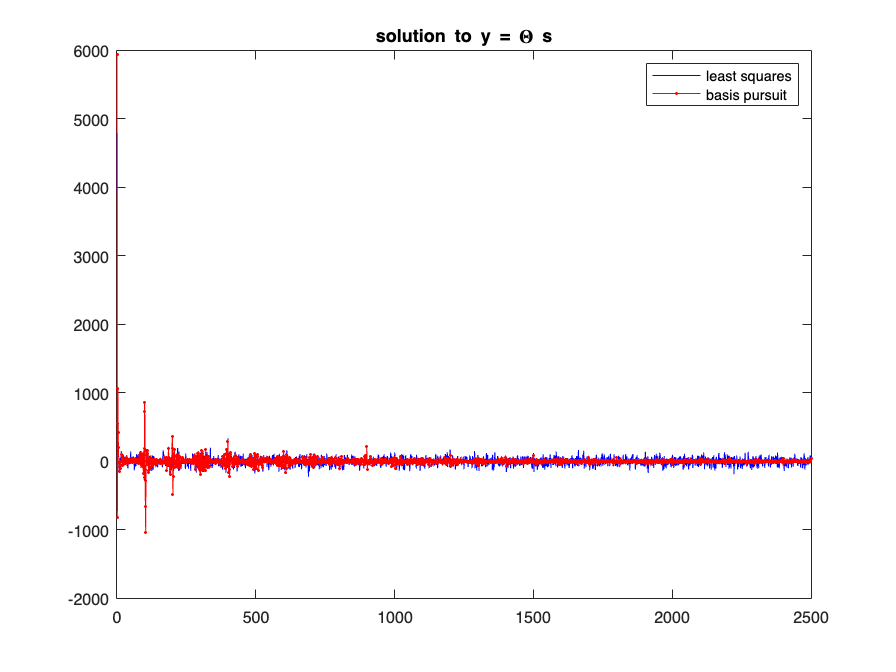

plot(s1,'r.-')
legend('least squares','basis pursuit')
title('solution to y = \Theta s')

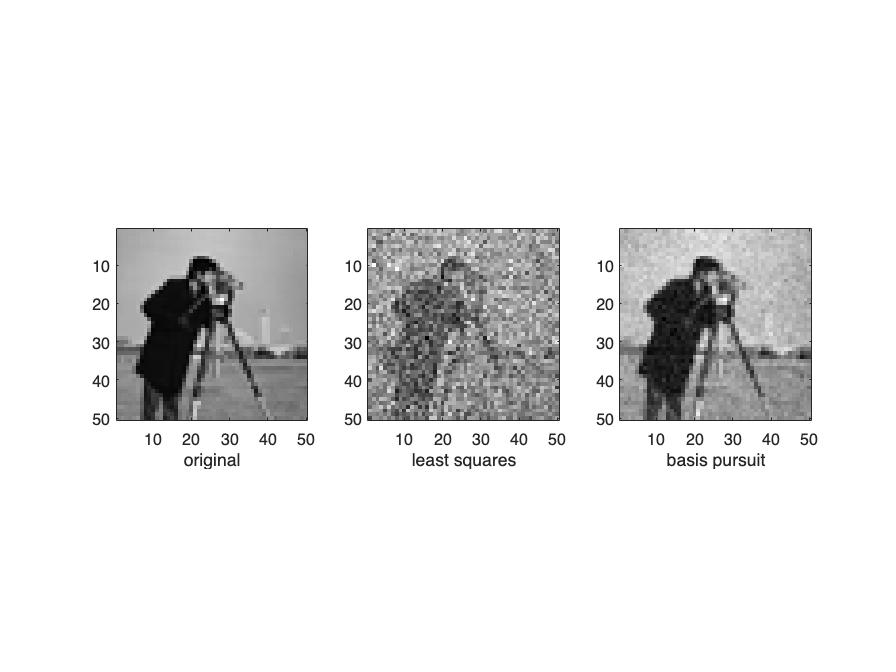

%___IMAGE RECONSTRUCTIONS___
x2 = zeros(n,1);
for ii = 1:n
    ii;
    ek = zeros(1,n);
    ek(ii) = 1;
    psi = idct(ek)';
    x2 = x2+psi*s2(ii);
end
x1 = zeros(n,1);
for ii = 1:n
    ii;
    ek = zeros(1,n);
    ek(ii) = 1;
    psi = idct(ek)';
    x1 = x1+psi*s1(ii);
end
figure('name','Compressive sensing image reconstructions')
subplot(1,3,1), imagesc(reshape(x,50,50)), xlabel('original'), axis image
subplot(1,3,2), imagesc(reshape(x2,50,50)), xlabel('least squares'), axis image
subplot(1,3,3), imagesc(reshape(x1,50,50)), xlabel('basis pursuit'), axis image
colormap gray